close("all"); clear; clc;

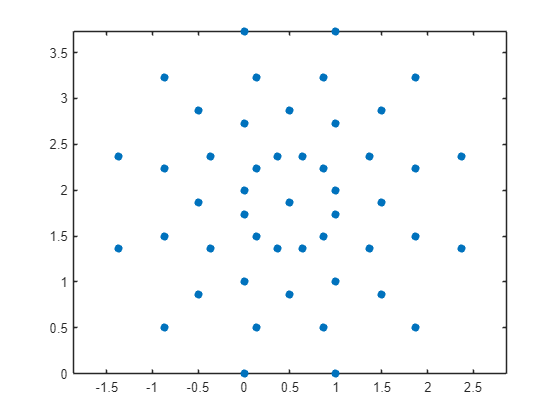

n = 12;
ang = 0:2*pi/n:((n/2 - 1)*2*pi/n);
f = @(a)([cos(a),-sin(a);sin(a),cos(a)]*[1;0]).';
G = cell2mat(arrayfun(f,ang.',"uniform",0));

P = vertices(G);
scatter(P(:,1),P(:,2),"filled");
axis("equal");
box("on");

S = G([3,4],:);

tic;
flag = true;
for i = 1:2^size(G,1) - 1
    inds = logical(dec2bin(i,size(G,1)) - '0').';
    T = G(inds,:);
    if isequal(S,T)
        continue;
    end
    if abs(sum(S,1) - sum(T,1)) < 1E03*eps
        flag = false;
        break;
    end
end
toc;

Elapsed time is 0.008537 seconds.



flag

flag = logical
   0


Ga = G + abs(min(G(:)))

Ga =     1.8660    0.8660
    1.7321    1.3660
    1.3660    1.7321
    0.8660    1.8660
    0.3660    1.7321
         0    1.3660


function p = vertices(G)
    f = @(g)[zeros(size(g)),g];
    g = cellfun(f,num2cell(G.',1),"uniform",0);
    p = minkowskiSum(g{:}).';
end